# Ex1 CCM Compensate Example (Manual Adjust)

**ECIE Copyright Reserved**

Initialization

clear();

format shortEng;
cd(fileparts(matlab.desktop.editor.getActiveFilename))

Global bode plot figure size

bodePlotWidth = 450;
bodePlotHeight = 400;

bodeRange = [100 1e6];

Power stage parameters;

PS.Vin=48;
PS.Vo=12;
PS.Io=36;
PS.D1=PS.Vo/PS.Vin;     % D
PS.RL=PS.Vo/PS.Io;
PS.L=20e-6;
PS.C=100e-6;
PS.rC = 10e-3;
fs = 200e3;

Compensate parameters;

fcv = 20e3;   % ! Needs modification !
PM = 50;     % ! Needs modification !
Fm = 1;

## **1. Plant (Gvd)**

### **a. Small Signal (*Important)**

**CCM Small signal**

s = tf('s');

Gvd.var = PS.L;
Gvd.wzc = 1 / (PS.C*PS.rC);
Gvd.w0 = sqrt(1/(PS.L*PS.C));
Gvd.Q = (1/Gvd.w0) * (1/(PS.C*PS.rC+PS.L/PS.RL));
Gvd.tf = (PS.Vin * (1+s/Gvd.wzc)) /...
    (1+(1/Gvd.Q)*(s/Gvd.w0)+(s^2 / Gvd.w0^2));

Plant.tf = Gvd.tf * Fm;

### **b. Bode Plot Figure Initialization**

[axe_m,axe_p] = bodeplotFrame(bodePlotWidth,bodePlotHeight,"Step1. Plant (Gvd)");
legend(axe_m,'location','northeast');
%legend(axe_p,'location','northeast');
xlim(axe_m,bodeRange);
xlim(axe_p,bodeRange);
xline(axe_m , fcv,'HandleVisibility','off');
xline(axe_p , fcv,'HandleVisibility','off');

### c. Bode Plot

drawBodePlot(axe_m,axe_p,Plant.tf,bodeRange,sprintf('CCM'));
drawPoleAndZero(axe_m,axe_p,Plant.tf);

Result

fcv_phase = rad2deg(angle(freqresp(Plant.tf, fcv * (2*pi))));
PM_plant = fcv_phase + 180

PM_plant =     21.2336e+000



if PM_plant < 40
    disp("PM is not sufficient");
end

PM is not sufficient


### d. Bode Plot Compare (Simulation) **(*Important)**

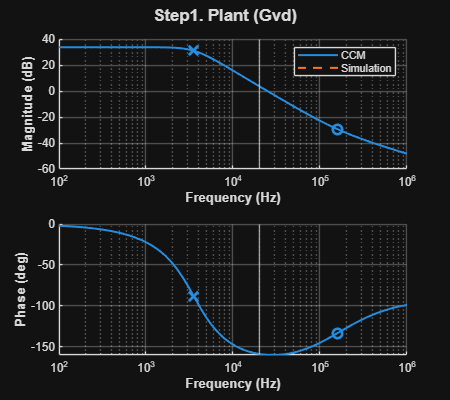

verifyBodePlot(axe_m, axe_p,"CCM/Gvd.txt","Simulation");

## **2. Compensate  Phase**

### **a. Compensator Settings (*Important)**

disp("========== Compensate Phase ==========");

========== Compensate Phase ==========


fcv_phase = rad2deg(angle(freqresp(Plant.tf, fcv * (2*pi))));

PM_plant = fcv_phase + 180;
PM_boost = PM - PM_plant

PM_boost =     28.7664e+000



$$G(s)=Kd\frac{\omega_i(1+\frac{s}{\omega_{z1}})(1+\frac{s}{\omega_{z2}})}{s(1+\frac{s}{\omega_{p1}})(1+\frac{s}{\omega_{p2}})}$$


Gvd.w0 / (2*pi)

ans =      3.5588e+003



Gea.fz1=562;    % ! Needs modification !
Gea.fz2=695;    % ! Needs modification !

Gea.fp1=8000;   % ! Needs modification !
Gea.fp2=9000;   % ! Needs modification !

Gea.wz1 = Gea.fz1 * (2*pi);
Gea.wz2 = Gea.fz2* (2*pi);

Gea.wp1 = Gea.fp1* (2*pi);
Gea.wp2 = Gea.fp2* (2*pi);

s = tf('s');
Gea.tf = (1+s/Gea.wz1)*(1+s/Gea.wz2)/...
    (s*(1+s/Gea.wp1)*(1+s/Gea.wp2));

Controller = Gea;
Loop.tf = Plant.tf * Controller.tf;

% Compensated Result
Phase_target = PM_boost

Phase_target =     28.7664e+000


Phase_current = rad2deg(angle(freqresp(Gea.tf, fcv * (2*pi))))

Phase_current =    -47.5707e+000


### **b. Bode Plot Figure Initialization**

[axe_m,axe_p] = bodeplotFrame(bodePlotWidth,bodePlotHeight,"Step2. Gea (Phase Compensated)");
legend(axe_m,'location','northeast');
legend(axe_p,'location','northeast');
xlim(axe_m,bodeRange);
xlim(axe_p,bodeRange);
xline(axe_m , fcv,'HandleVisibility','off');
xline(axe_p , fcv,'HandleVisibility','off');

### **c. Bode Plot**

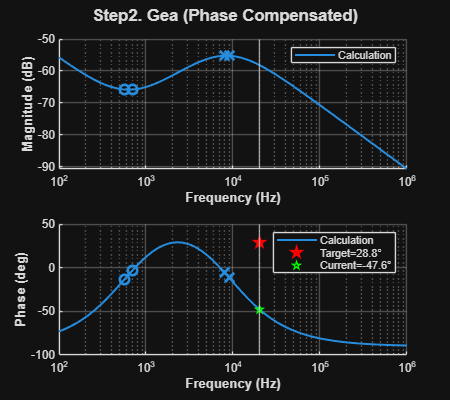

drawBodePlot(axe_m,axe_p,Gea.tf ,bodeRange,sprintf('Calculation'));
drawPoleAndZero(axe_m,axe_p,Gea.tf );

plot(fcv, PM_boost, ...
    'pentagram', ...
    'linewidth',2, ...
    'Color','r', ...
    'DisplayName',sprintf("Target=%s°",engFormat(PM_boost)));
previousColor();

plot(fcv, Phase_current , ...
    'p', ...
    'linewidth',1, ...
    'Color','g', ...
    'DisplayName',sprintf("Current=%s°",engFormat(Phase_current)));
previousColor();

### **d. Loop Bode Plot Figure Initialization**

[axe_m,axe_p] = bodeplotFrame(bodePlotWidth,bodePlotHeight,"Step2. Loop (Phase Compensated)");
legend(axe_m,'location','northeast');
legend(axe_p,'location','northeast');
xlim(axe_m,bodeRange);
xlim(axe_p,bodeRange);
xline(axe_m , fcv,'HandleVisibility','off');
xline(axe_p , fcv,'HandleVisibility','off');
yline(axe_p, -180,'HandleVisibility','off');

### **e.Loop Bode Plot**

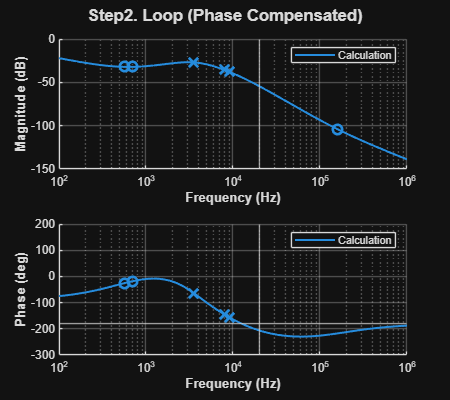

drawBodePlot(axe_m,axe_p,Loop.tf,bodeRange,sprintf('Calculation'));
drawPoleAndZero(axe_m,axe_p,Loop.tf);

### **f. Result**

PM

PM =     50.0000e+000


PM_new = rad2deg(angle(freqresp(Loop.tf, fcv*(2*pi)))) + 180

PM_new =    333.6630e+000



fcv_gain = mag2db(abs(freqresp(Loop.tf,fcv * (2*pi))))

fcv_gain =    -54.3900e+000


## **3. Compensate Gain**

### **a. Calculation (*Important)  **

disp("========== Compensate Gain ==========");

========== Compensate Gain ==========


Controller_Original = Controller;

fcv_gain = mag2db(abs(freqresp(Loop.tf,fcv * (2*pi))));

Gain_boost = -1 * fcv_gain

Gain_boost =     54.3900e+000


Gea.wi = db2mag(Gain_boost);
Gea.tf = Gea.tf * db2mag(Gain_boost);
Controller = Gea;

### **b. Bode Plot Figure Initialization **

[axe_m,axe_p] = bodeplotFrame(bodePlotWidth,bodePlotHeight,"Step3. Gea (Gain Compensated)");
legend(axe_m,'location','northeast');
legend(axe_p,'location','northeast');
xlim(axe_m,bodeRange);
xlim(axe_p,bodeRange);
xline(axe_m , fcv,'HandleVisibility','off');
xline(axe_p , fcv,'HandleVisibility','off');

### **c. Bode Plot**

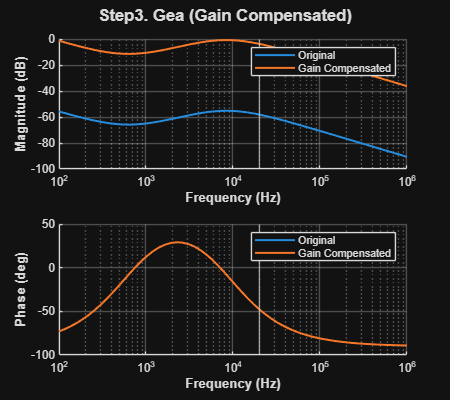

drawBodePlot(axe_m,axe_p,Controller_Original.tf,bodeRange,sprintf('Original'));
drawBodePlot(axe_m,axe_p,Controller.tf,bodeRange,sprintf('Gain Compensated'));

## **4. OPA Compensator Design**


$$Gea(s)=\frac{(C_{FS}R_{F}s+1)\cdot(C_{I}R_{IP}s+C_{I}R_{IS}s+1))}{R_{IP}s\cdot(C_I\ R_{IS}s+1)\cdot(C_FP+C_FS+C_{FP}C_{FS}R_Fs)}$$


**a. Basic Parameter**

disp("========== Step4. OPA Design ==========");

========== Step4. OPA Design ==========


Vref = 2.5

Vref =      2.5000e+000


OPA.Rf = 1e3;

Calculate OPA parameters;

OPA.Fi = Controller.wi / (2*pi);
OPA.Rf = 1e3;
OPA.Cfs = 1 / (Controller.wz1 * OPA.Rf);
OPA.Cfp = 1 / (Controller.wp2 * OPA.Rf - 1/OPA.Cfs);
OPA.Rip = 1 / (2*pi*OPA.Fi*(OPA.Cfs+OPA.Cfp));
OPA.Ris = OPA.Rip / (Controller.wp1 / Controller.wz2 - 1);
OPA.Ci = 1 / (Controller.wp1*OPA.Ris);

OPA.Rbias = OPA.Rip*Vref / (PS.Vo-Vref);

s=tf('s');
OPA.tf = (OPA.Cfs*OPA.Rf*s + 1) * (OPA.Ci*OPA.Rip*s+OPA.Ci*OPA.Ris*s+1) /...
    ((OPA.Rip*s)*(OPA.Ci*OPA.Ris*s+1)*(OPA.Cfp+OPA.Cfs+OPA.Cfp*OPA.Cfs*OPA.Rf*s));

OPA

OPA = struct with fields:
       Rf: 1.0000e+003
       Fi: 83.4296e+000
      Cfs: 283.1938e-009
      Cfp: 18.8617e-009
      Rip: 6.3156e+003
      Ris: 600.8661e+000
       Ci: 33.1095e-009
    Rbias: 1.6620e+003
       tf: [1×1 tf]


### **b. Bode Plot Figure Initialization **

[axe_m,axe_p] = bodeplotFrame(bodePlotWidth,bodePlotHeight,"Step4. OPA Design");
legend(axe_m,'location','northeast');
legend(axe_p,'location','northeast');
xlim(axe_m,bodeRange);
xlim(axe_p,bodeRange);
xline(axe_m , fcv,'HandleVisibility','off');
xline(axe_p , fcv,'HandleVisibility','off');


### **c. Bode Plot**

drawBodePlot(axe_m,axe_p,Gea.tf,bodeRange,sprintf('Calculation'));
drawPoleAndZero(axe_m,axe_p,Gea.tf);

drawBodePlot(axe_m,axe_p,OPA.tf,bodeRange,sprintf('OPA'));


### d. Bode Plot Compare (Simulation) **(*Important)**

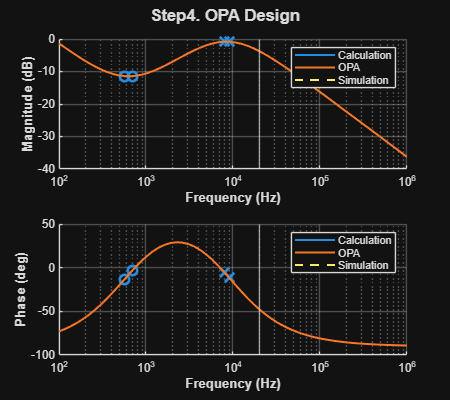

verifyBodePlot(axe_m, axe_p,"CCM/Gea.txt","Simulation",-180);

## **5. Loop Gain Verify**

### **a. Calculation (*Important)  **

disp("========== Step5. Loop Gain Verify ==========");

========== Step5. Loop Gain Verify ==========


Loop.tf = Plant.tf * Controller.tf;

% Validate
[~,Pm,~,Wcp] = margin(Loop.tf);

fcv_new = Wcp / (2*pi)

fcv_new =     19.9999e+003


fcv_gain = mag2db(abs(freqresp(Loop.tf,fcv_new*(2*pi))))

fcv_gain =    123.4178e-006


fcv_phase = rad2deg(angle(freqresp(Loop.tf, fcv_new*(2*pi))))

fcv_phase =    153.6632e+000


fcv_pm = (fcv_phase) + 180

fcv_pm =    333.6632e+000


### **b. Bode Plot Figure Initialization **

[axe_m,axe_p] = bodeplotFrame(bodePlotWidth,bodePlotHeight,"Step5. Loop");
legend(axe_m,'location','northeast');
legend(axe_p,'location','northeast');
xlim(axe_m,bodeRange);
xlim(axe_p,bodeRange);
xline(axe_m , fcv,'HandleVisibility','off');
xline(axe_p , fcv,'HandleVisibility','off');
currentYLim = ylim;
ylim(axe_p,[-180 currentYLim(2)])

### **c. Bode Plot**

drawBodePlot(axe_m,axe_p,Loop.tf,bodeRange,sprintf('Calculation'));
drawPoleAndZero(axe_m,axe_p,Loop.tf);
drawMargin(axe_m,axe_p,Loop.tf);

### d. Bode Plot Compare (Simulation) **(*Important)**

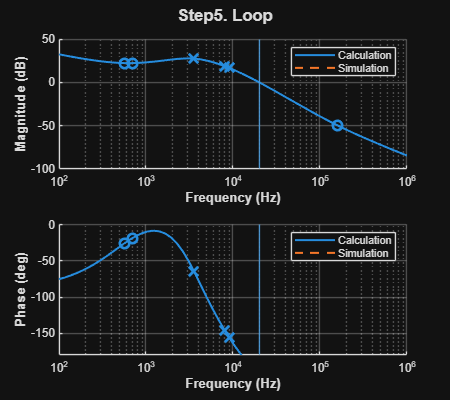

verifyBodePlot(axe_m, axe_p,"CCM/Loop.txt","Simulation",-180);

## **Function Definition**

function [axe_m, axe_p] = bodeplotFrame(width,height,titleName)
% Figure
f = figure();
f.Position(3) = width;
f.Position(4) = height;

sgtitle(titleName,'FontWeight','bold')

% Gain
axe_m = subplot(2, 1, 1);
grid on;
hold on;
set(axe_m,'XScale','log');

xlabel("Frequency (Hz)","FontWeight",'bold');
ylabel("Magnitude (dB)",'FontWeight','bold');

% Phase
axe_p = subplot(2, 1, 2);
grid on;
hold on;
set(axe_p,'XScale','log');

xlabel("Frequency (Hz)","FontWeight",'bold');
ylabel("Phase (deg)",'FontWeight','bold');
end

function [axe_m, axe_p] = drawBodePlot(axe_m, axe_p, tf , bodeRange, displayName)

[mag,phase,wout] = bode(tf  ,num2cell(bodeRange*2*pi));
fout = wout ./ (2*pi);
mag = mag2db(squeeze(mag));
phase = squeeze(phase);

%displayName = 'Calculation';

semilogx(axe_m,fout,mag, ...
    'DisplayName',displayName,...
    'LineWidth',1.5);

semilogx(axe_p,fout,phase, ...
    'DisplayName',displayName,...
    'LineWidth',1.5);
end

function [axe_m, axe_p] = drawPoleAndZero(axe_m, axe_p, tf)

previousColor(axe_m);
previousColor(axe_p);
wp = abs(pole(tf));
wp_m = mag2db(abs(freqresp(tf,wp)));
wp_p = rad2deg(angle(freqresp(tf, wp)));
scatter(axe_m, real(wp/(2*pi)), wp_m(:), 100, 'x', 'LineWidth', 2, 'DisplayName', 'Poles','HandleVisibility','off');
scatter(axe_p, real(wp/(2*pi)), wp_p(:), 100, 'x', 'LineWidth', 2, 'DisplayName', 'Poles','HandleVisibility','off');

previousColor(axe_m);
previousColor(axe_p);
wz = abs(zero(tf));
wz_m = mag2db(abs(freqresp(tf,wz)));
wz_p = rad2deg(angle(freqresp(tf, wz)));
scatter(axe_m, real(wz/(2*pi)), wz_m(:), 50, 'o', 'LineWidth', 2, 'DisplayName', 'Zeros','HandleVisibility','off');
scatter(axe_p, real(wz/(2*pi)), wz_p(:), 50, 'o', 'LineWidth', 2, 'DisplayName', 'Zeros','HandleVisibility','off');

end

function [fcv, Pm] = drawMargin(axe_m, axe_p, Loop)
[~,Pm,~,Wcp] = margin(Loop);
fcv = Wcp / (2*pi);

% Draw fcv xline
colorIndex = axe_m.ColorOrderIndex - 1;
colors = colororder;
xline(axe_m , fcv,'HandleVisibility','off','Color',colors(colorIndex,:,:));
xline(axe_p , fcv,'HandleVisibility','off','Color',colors(colorIndex,:,:));
end

function [fcv, Pm] = getMargin(Loop)
[~,Pm,~,Wcp] = margin(Loop);
fcv = Wcp / (2*pi);
end

function [axe_m, axe_p] = verifyBodePlot(axe_m, axe_p, file,displayName,varargin)
Sim.file = file;
if isfile(Sim.file)
    Sim.data = readmatrix(Sim.file);
    Sim.freq = Sim.data(:,1);
    Sim.amplitude = Sim.data(:,2);
    Sim.phase = Sim.data(:,3);


    if nargin > 4
        Sim.phase = Sim.phase + varargin{1};
    end


    plot(axe_m,Sim.freq,Sim.amplitude, ...
        'LineWidth',1.5, ...
        'LineStyle','--',...
        'DisplayName',displayName);

    semilogx(axe_p,Sim.freq,Sim.phase, ...
        'LineWidth',1.5, ...
        'LineStyle','--',...
        'DisplayName',displayName);
else
    warning(join(["File not found:'" Sim.file "'"],""));
end
end

function OPA = opaCompParameter(Controller, Vo, Vref)
OPA.Fi = Controller.wi / (2*pi);
OPA.Rf = 1e3;
OPA.Cfs = 1 / (Controller.wz1 * OPA.Rf);
OPA.Cfp = 1 / (Controller.wp2 * OPA.Rf - 1/OPA.Cfs);
OPA.Rip = 1 / (2*pi*OPA.Fi*(OPA.Cfs+OPA.Cfp));
OPA.Ris = OPA.Rip / (Controller.wp1 / Controller.wz2 - 1);
OPA.Ci = 1 / (Controller.wp1*OPA.Ris);

OPA.Rbias = OPA.Rip*Vref / (Vo-Vref);

s=tf('s');
OPA.tf = (OPA.Cfs*OPA.Rf*s + 1) * (OPA.Ci*OPA.Rip*s+OPA.Ci*OPA.Ris*s+1) /...
    ((OPA.Rip*s)*(OPA.Ci*OPA.Ris*s+1)*(OPA.Cfp+OPA.Cfs+OPA.Cfp*OPA.Cfs*OPA.Rf*s));
end

function output_str = opaToSimplis(OPA)
fields = fieldnames(OPA);
output_str = '';

for i = 1:numel(fields)
    field_name = fields{i};
    field_value = OPA.(field_name);
    if (~isnumeric(field_value))
        continue;
    end
    field_str = sprintf(".VAR %s = %s\n", field_name, engFormat(field_value));
    output_str = append(output_str,field_str);
end
disp(output_str)
end

function str = engFormat(value)
exponent = floor(log10(abs(value)));  % Calculate the base-10 exponent
engExponent = exponent - mod(exponent, 3);  % Adjust the exponent to be a multiple of 3 (engineering format)
scaledValue = value / 10^engExponent;  % Scale the value to the appropriate range

% Format the value part
str = sprintf('%.3g', scaledValue);

% Append the exponent part only if engExponent is not 0
if engExponent ~= 0
    str = [str 'e' num2str(engExponent)];
end
end

function previousColor(varargin)
axe = gca();
if (nargin == 1)
    axe = varargin(1);
    axe = axe{1};
elseif (nargin > 1)
    return;
end

prevColorIndex = axe.ColorOrderIndex-1;

if (prevColorIndex == 0)
    colorOrderSize = size(axe.ColorOrder);
    prevColorIndex = colorOrderSize(1);
end

axe.ColorOrderIndex = prevColorIndex;
end